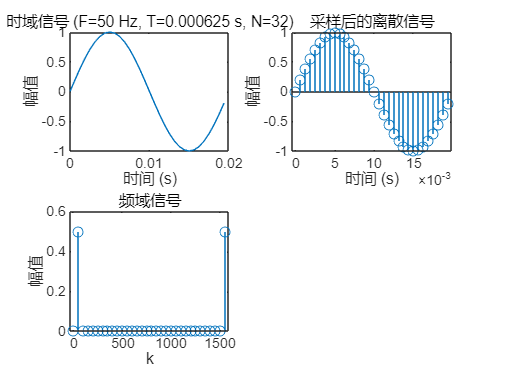

% 定义绘图函数，方便在不同情况下绘制时域和频域图
function plot_time_freq(F, T, N, zero_padding)
    % F: 信号频率
    % T: 采样间隔
    % N: 采样点数
    % zero_padding: 补零至2*N个样点的开关
    
    t = (0:N-1) * T; % 生成时域采样点
    x = sin(2*pi*F*t); % 生成正弦信号
    
    % 补零选项
    if zero_padding
        x = [x, zeros(1, N)]; % 补零至2*N样点
        N = 2 * N; % 更新样点数
    end
    
    % 计算 FFT
    X = fft(x); % 计算 FFT
    f = (0:N-1) * (1/(N*T)); % 生成频率轴

    % 绘制时域图
    figure;
    subplot(2,2,1);
    plot((0:N-1)*T, x);
    title(['时域信号 (F=', num2str(F), ' Hz, T=', num2str(T), ' s, N=', num2str(N), ')']);
    xlabel('时间 (s)');
    ylabel('幅值');

    subplot(2,2,2);
    stem((0:N-1)*T, x);
    title(['采样后的离散信号']);
    xlabel('时间 (s)');
    ylabel('幅值');

    % 绘制频域图
    subplot(2,2,3);
    stem(f, abs(X)/N); % 归一化幅值
    title('频域信号');
    xlabel('k');
    ylabel('幅值');
end

% a) F=50Hz, N=32, T=0.000625s
plot_time_freq(50, 0.000625, 32, 0);

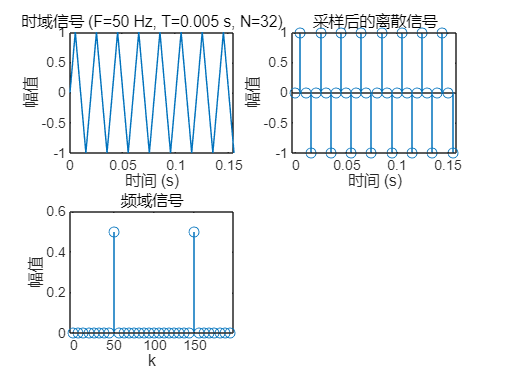


% b) F=50Hz, N=32, T=0.005s
plot_time_freq(50, 0.005, 32, 0);

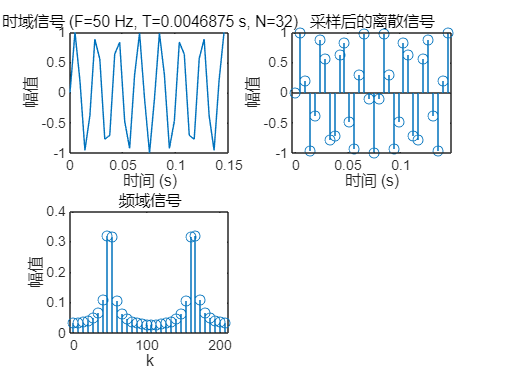


% c) F=50Hz, N=32, T=0.0046875s
plot_time_freq(50, 0.0046875, 32, 0);

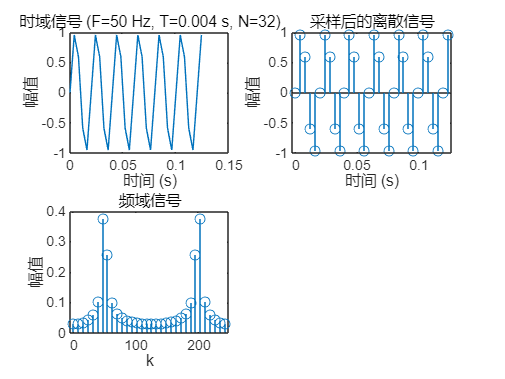


% d) F=50Hz, N=32, T=0.004s
plot_time_freq(50, 0.004, 32, 0);

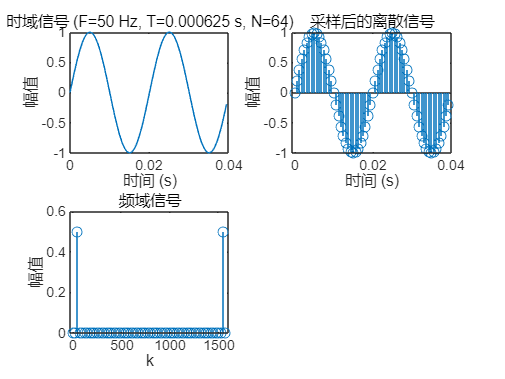


% e) F=50Hz, N=64, T=0.000625s
plot_time_freq(50, 0.000625, 64, 0);

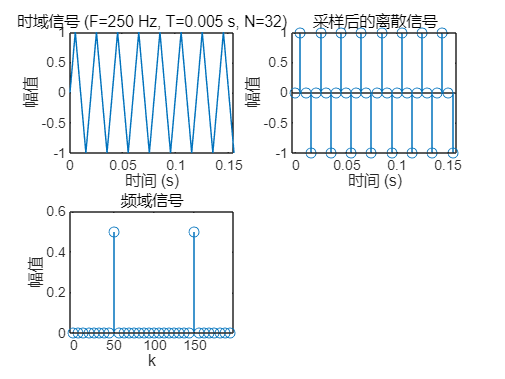


% f) F=250Hz, N=32, T=0.005s
plot_time_freq(250, 0.005, 32, 0);

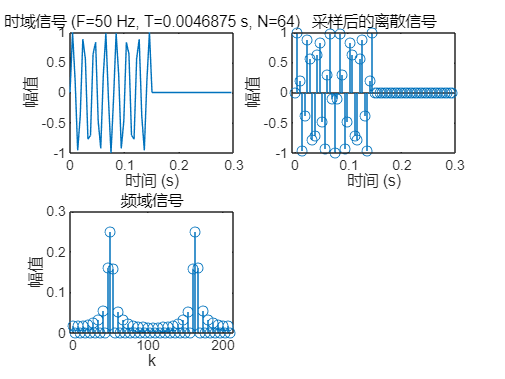


% g) F=50Hz, N=32, T=0.0046875s, 信号补零至64个样点
plot_time_freq(50, 0.0046875, 32, 1);